## **Driver test program to check Clothoids library**

**Test G2 clothoid**

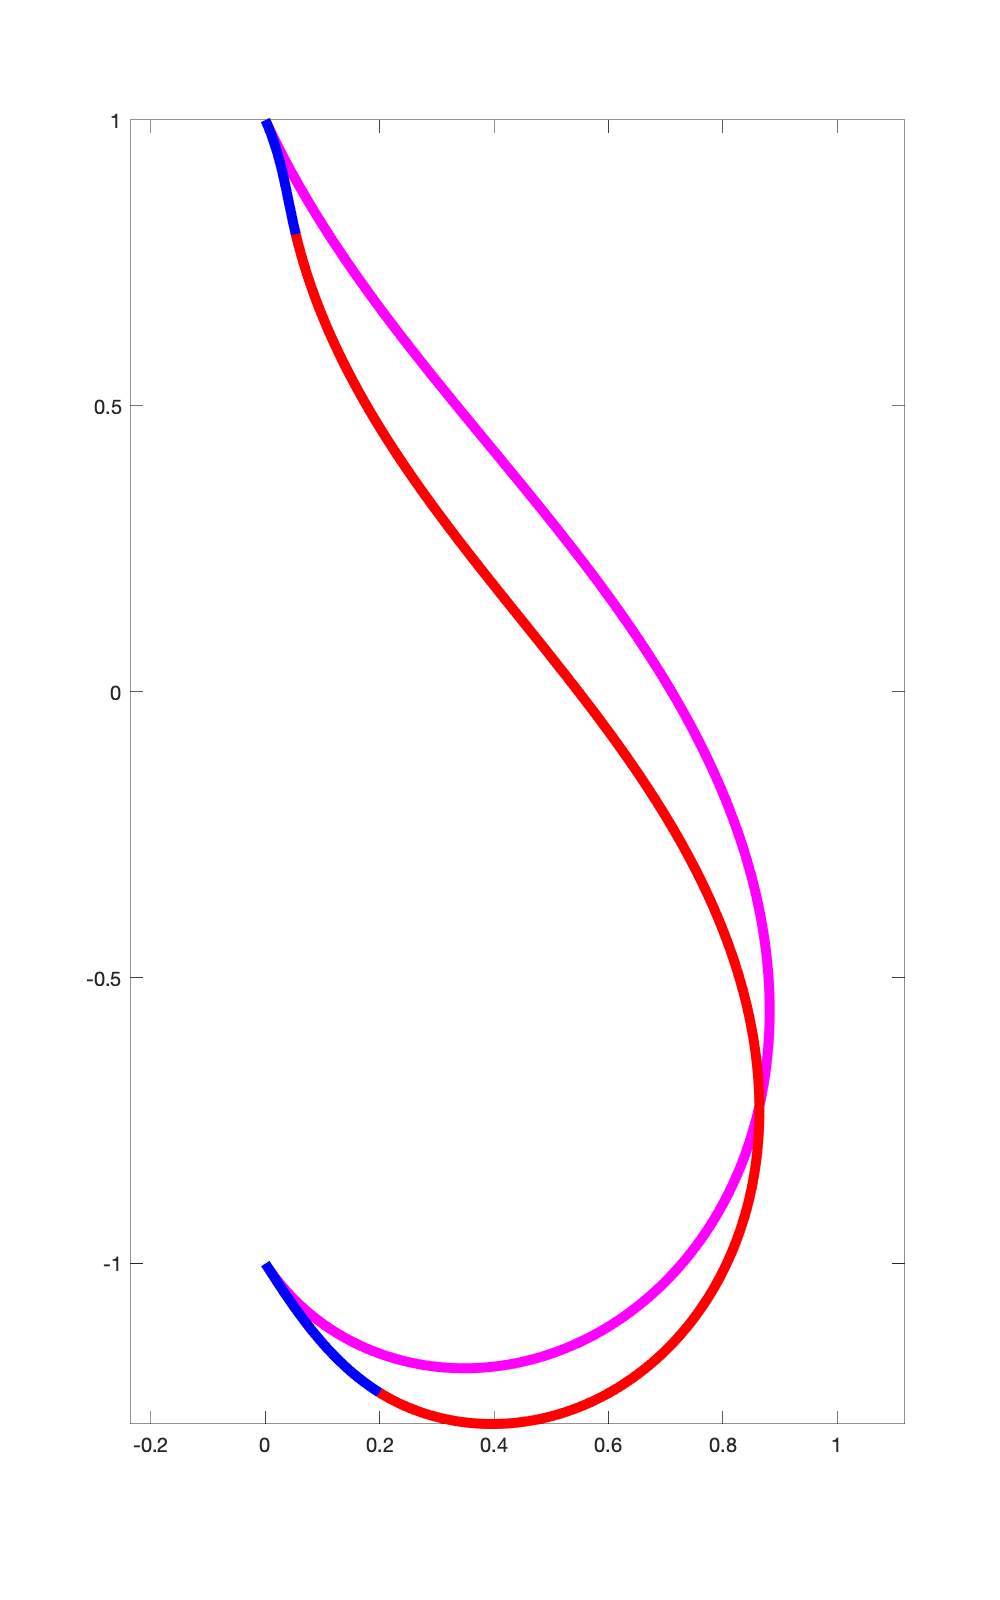

close all;

x0     = 0;
y0     = -1;
theta0 = -1;
kappa0 = 0.1;


x1     = 0;
y1     = 1;
theta1 = 2;
kappa1 = 3;

close all;
figure('Position',[1,1,500,800]);

C = ClothoidCurve();
S = ClothoidList();

C.build_G1( x0, y0, theta0, ...
            x1, y1, theta1 );
S.build_3arcG2( x0, y0, theta0, kappa0, ...
                x1, y1, theta1, kappa1);

C.plot(1000,'-m','Linewidth',5);
hold on;
S.plot(1000,{'-r','Linewidth',5},{'-b','Linewidth',5});
axis equal;